**Load the signal ecg.txt (fs=256 Hz). Do the spectral analysis and detect the artefacts. **

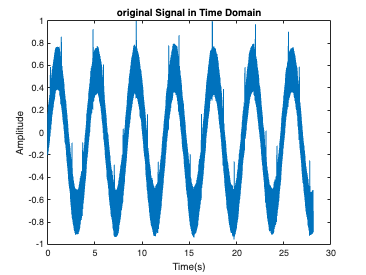

load ecg.mat
fs = 256;
t=linspace(0,length(ecg)/fs,length(ecg));
figure()
plot(t,ecg/max(ecg));
title('original Signal in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

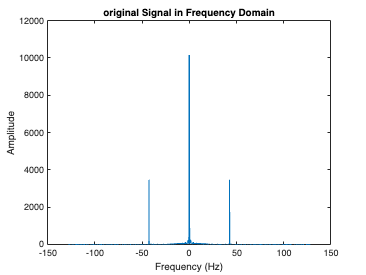


figure()
ecg=ecg-mean(ecg); % Per visualizzare meglio lo spettro
f=linspace(-fs/2,fs/2,length(ecg));
plot(f,fftshift(abs(fft(ecg))));
title('original Signal in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');

42 Hz -> power line interference (artefatti da strumentazione) -> filtro stop band

**What kind of filters do you need to design to remove artifacts? **				

**Try to design the filters.**

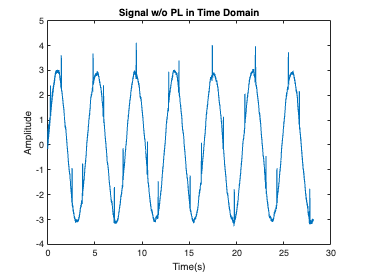

[b,a]=butter(4,[41,43]/(fs/2),'stop');
sig_f=filtfilt(b,a,ecg);

plot(t,sig_f)
title('Signal w/o PL in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

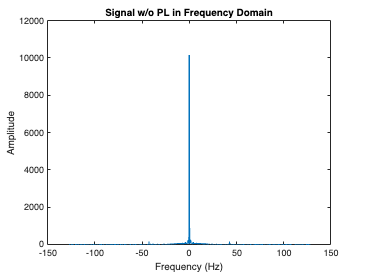


figure()
plot(f,fftshift(abs(fft(sig_f))));
title('Signal w/o PL in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

rimuovo anche 0,5 Hz -> high pass

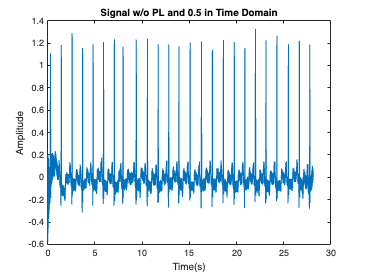

[b,a]=butter(4,[0.5]/(fs/2),'high');
sig_f1=filtfilt(b,a,sig_f);

plot(t,sig_f1)
title('Signal w/o PL and 0.5 in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

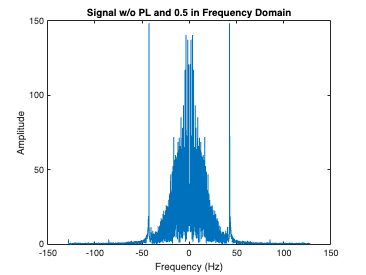


figure()
plot(f,fftshift(abs(fft(sig_f1))));
title('Signal w/o PL and 0.5 in Frequency Domain');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

**Use the smooth function to remove the baseline wander. **

n = length(sig_f1);
signal = sig_f1 - mean(sig_f1) % tolgo la BL e va a zero

signal =    -0.4900
   -0.0709
    0.1802
    0.0310
   -0.3517
   -0.5787
   -0.4268
   -0.0510
    0.2053
    0.0633


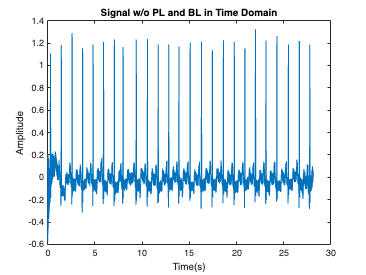


m = smoothdata(sig_f1,n); % n è la lunghezza del segnale

plot(t,signal)
title('Signal w/o PL and BL in Time Domain');
xlabel('Time(s)');
ylabel('Amplitude');

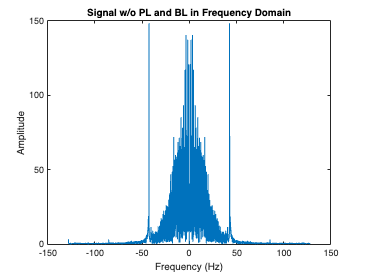


figure()
f=linspace(-fs/2,fs/2,length(m));
plot(f,fftshift(abs(fft(signal))));
title('Signal w/o PL and BL in Frequency Domain'); 
xlabel('Frequency (Hz)');
ylabel('Amplitude');